# Analize Volve 2008 velocity model

## Introduction

Example how to read Volve 2008 velocity models

**Author**: Ivan Abakumov

**Publication date**: 31st January 2019

**E-mail**: [abakumov_ivan@mail.ru](mailto:abakumov_ivan@mail.ru)

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## VTI velocity model, 2008

%filename = '/data2/ST0202/Velocities/VTI_model_2008/ST0202R08_PSDM_DELTA_FIELD_DEPTH.MIG_FIN.POST_STACK.3D.JS-017534.segy'; 
filename =  '/data2/ST0202/Velocities/VTI_model_2008/ST0202R08_S_WAVE_PSDM_FIELD_DEPTH.MIG_VEL.VELOCITY.3D.JS-017527.segy';
data = read_segy_file(filename); 
headers = get_segy_headers(data);


## Create G file

G = GridClass;
% X - inline
% Y - xline 
% Z - depth

%
G.x0 = min(headers.inline);
G.nx = max(headers.inline) - min(headers.inline) + 1; 
G.dx = 1; 
G.y0 = min(headers.xline);
G.ny = max(headers.xline) - min(headers.xline) + 1; 
G.dy = 1; 
G.z0 = 0;
G.nz = 451; 
G.dz = 10; 
G.t0 = 0.00;         
G.nt = 521;          
G.dt = 0.00025;      

G.gridInfo;

Information about grid:
x0=4953, dx=1, Nx=273.
y0=1748, dy=1, Ny=985.
z0=0, dz=10, Nz=451.
t0=0, dt=0.00025, Nt=521.


G.setGrid;


velmod = zeros(G.nx, G.ny, G.nz);


for i=1:size(data.traces,2)
    ing = x2grid(headers.inline(i), G.x0, G.dx, G.nx); 
    xlg = x2grid(headers.xline(i), G.y0, G.dy, G.ny); 
    velmod(ing,xlg,:) = data.traces(:,i);
end

## **Well info:**

/data2/Well_technical_data/WellWellbore/15_9-F-5

Well F-5

Well Position

Northing:  6478558.87 m    Latitude:   58° 26' 29.6569 N

Easting: 435050.94 m  Longitude:  1° 53' 14.9902 E

## Plot results

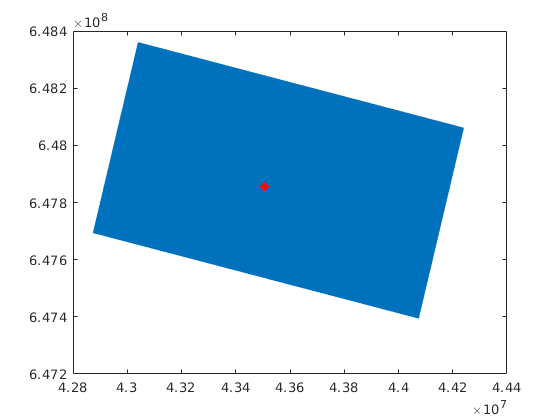

figure(334)
plot(headers.sx, headers.sy, '.')
hold on 
plot(43505094,647855887, 'r*')